# seStar-shaped Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on a Y-shaped graph, which is defined using the *star* template.

## Set up the graph structure and coordinates of the problem

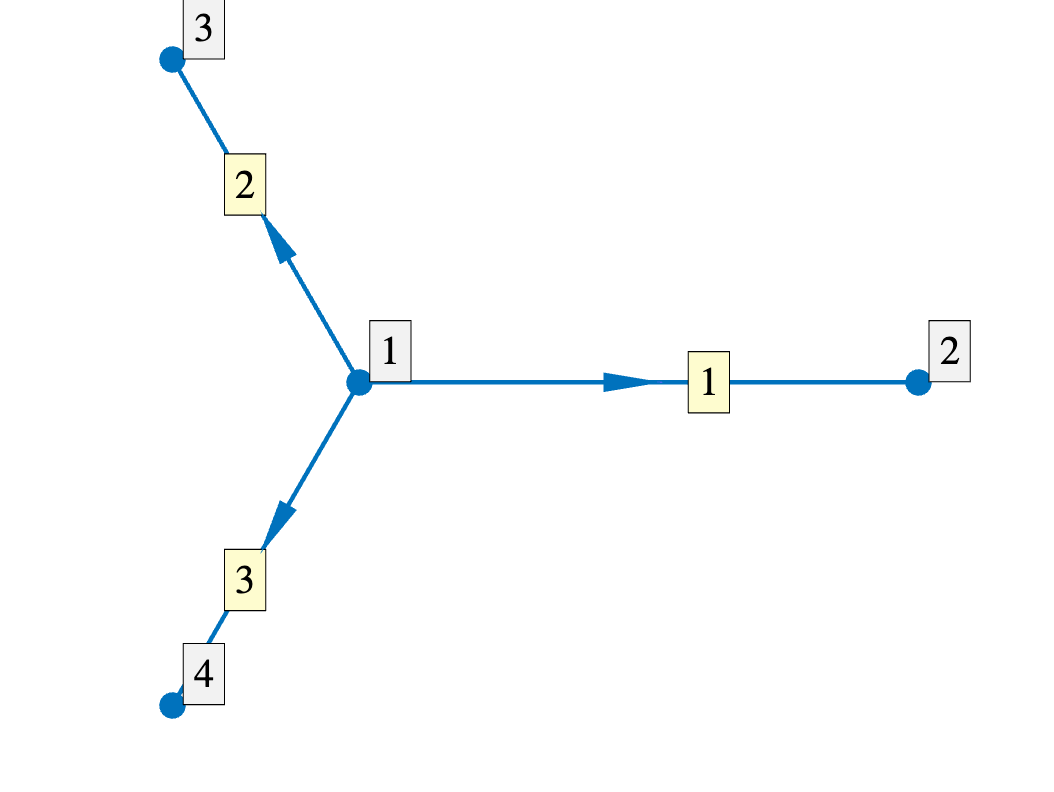

LVec=[1.5 1 1]; nX = 40; rC = [0 0 nan nan];
Phi = quantumGraphFromTemplate('star','LVec',LVec,'nX',nX,'robinCoeff',rC);
Phi.plot('layout')

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes calculated as positive and sometimes as negative and this messes up the sorting.

numEigs=7;
[V,lambda]=eigs(Phi,numEigs);
[singles,doubles,~]=separateEigs(lambda); % No triple eigenvalue unless handle and hoops resonant
nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

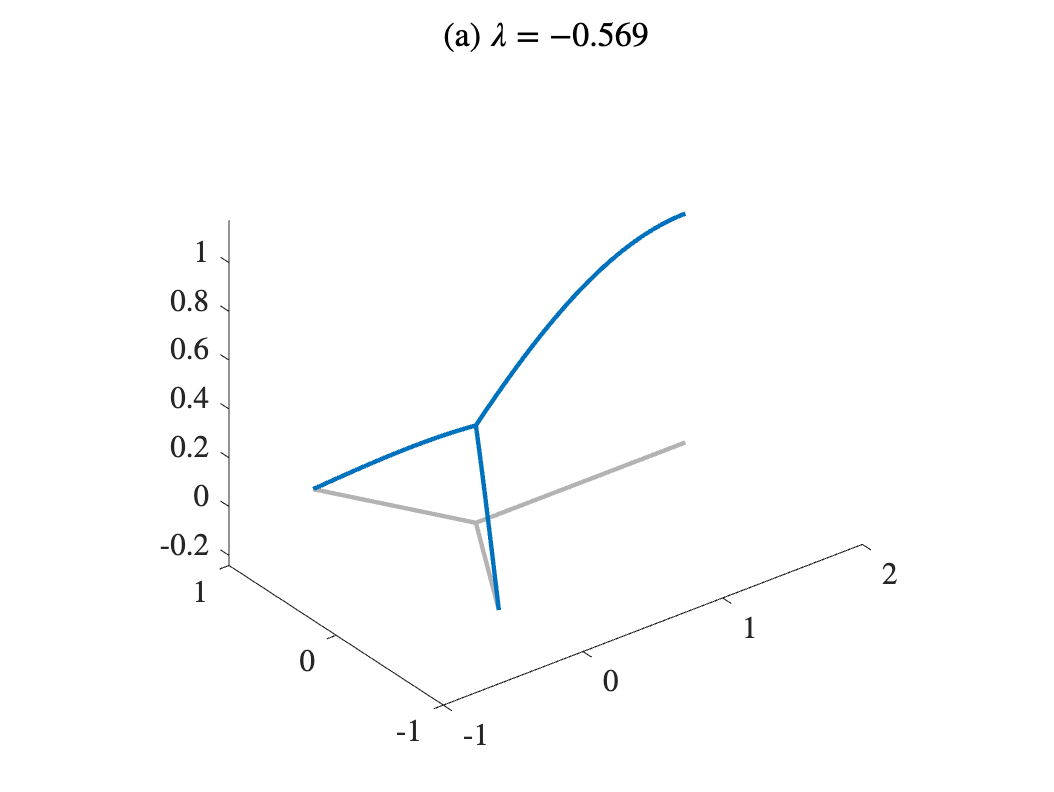

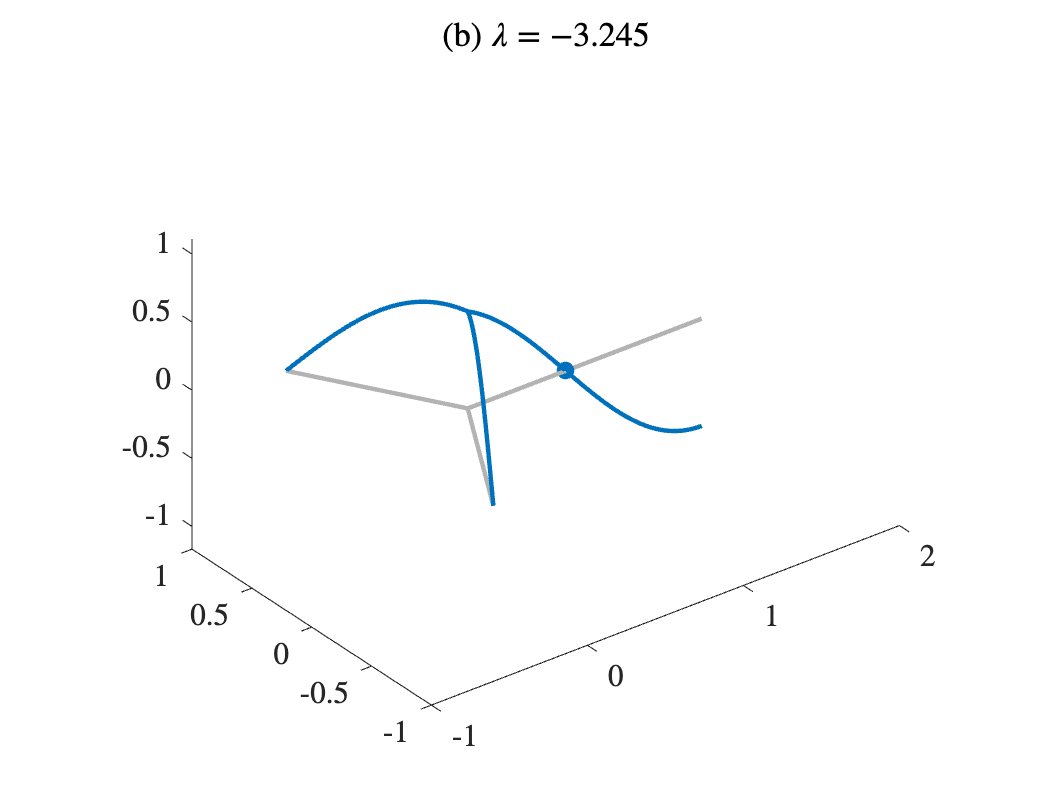

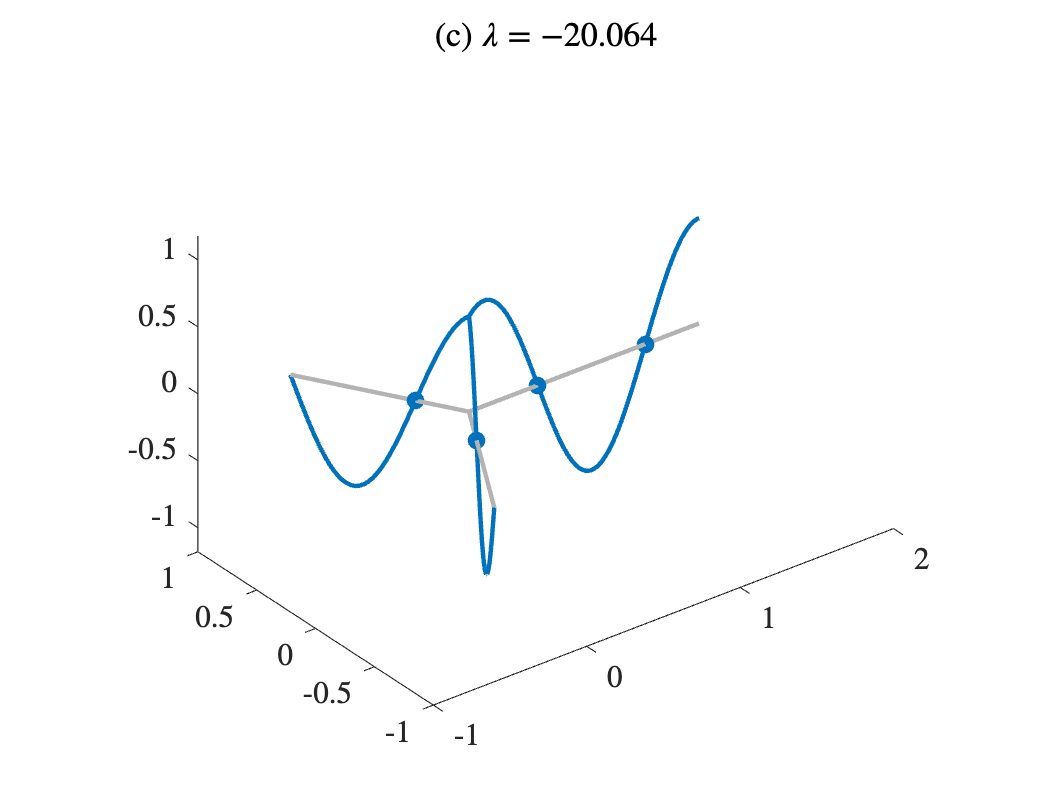

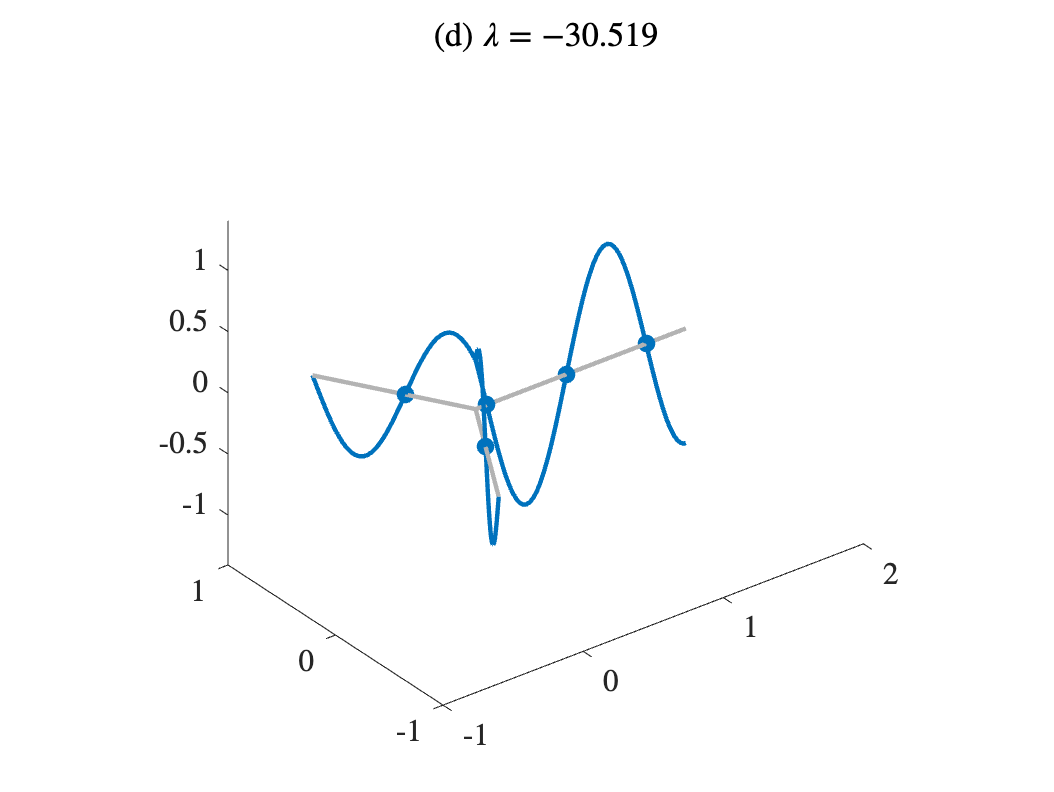

for k=1:nToPlot
    figure
    Phi.plot(V(:,singles(k)))
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(k),lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

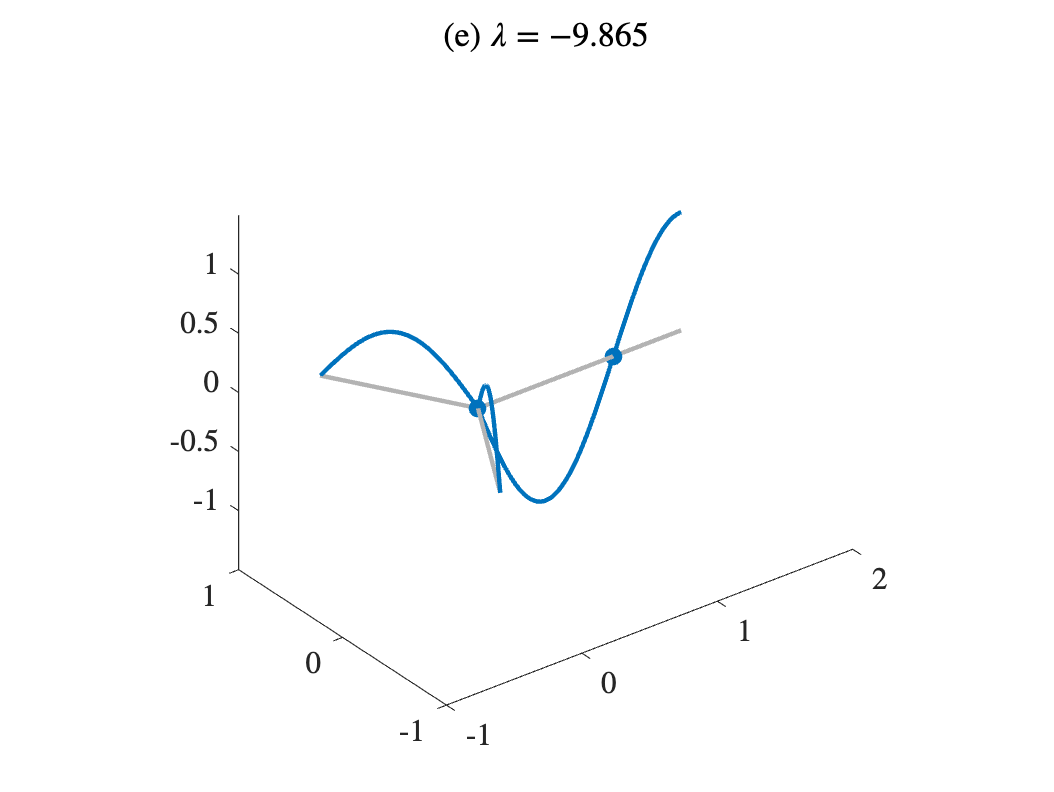

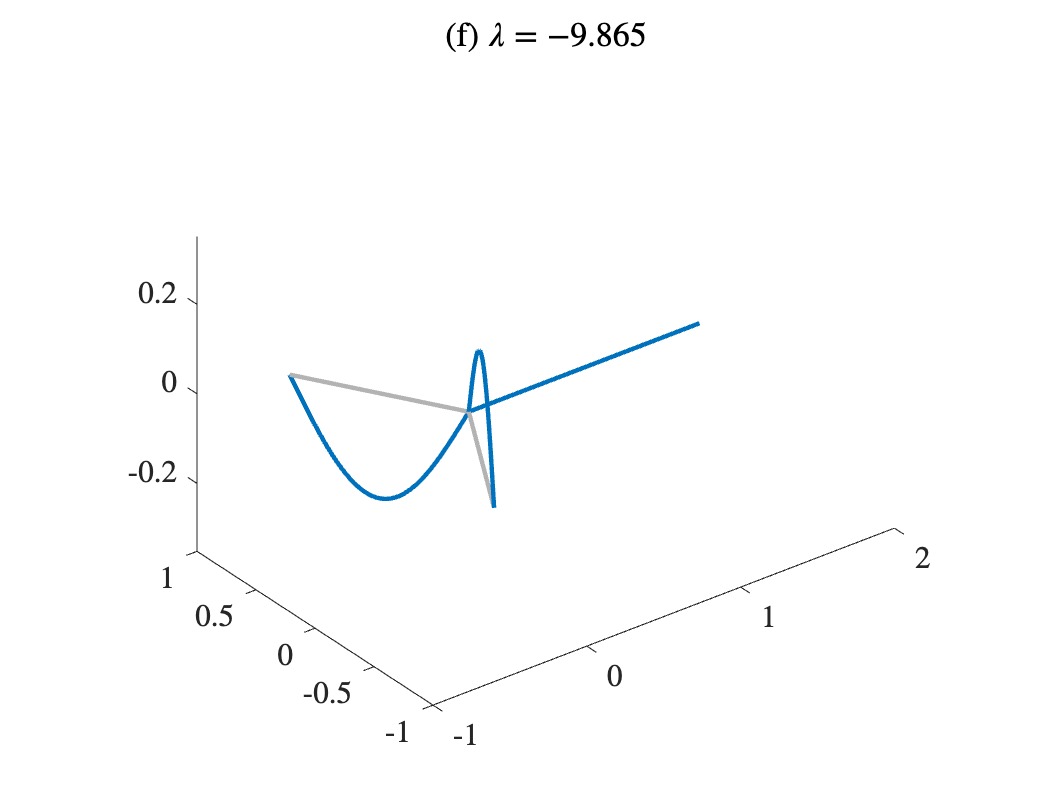

if ~isempty(doubles)    
    for k=1:min(nToPlot,length(doubles))
        v=starResolveDoubles(V,doubles(k),Phi);
        figure
        Phi.plot(v{1})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k-1), lambda(doubles(k))));
        figure
        Phi.plot(v{2})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k), lambda(doubles(k))));
    end
end

## Calculate and plot the secular determinant

f=Phi.secularDet

$$f = -\frac{16\,\sin\left(\frac{x}{2}\right)\,\left(12\,{\sin\left(\frac{x}{2}\right)}^{6}-21\,{\sin\left(\frac{x}{2}\right)}^{4}+10\,{\sin\left(\frac{x}{2}\right)}^{2}-1\right)}{3}$$

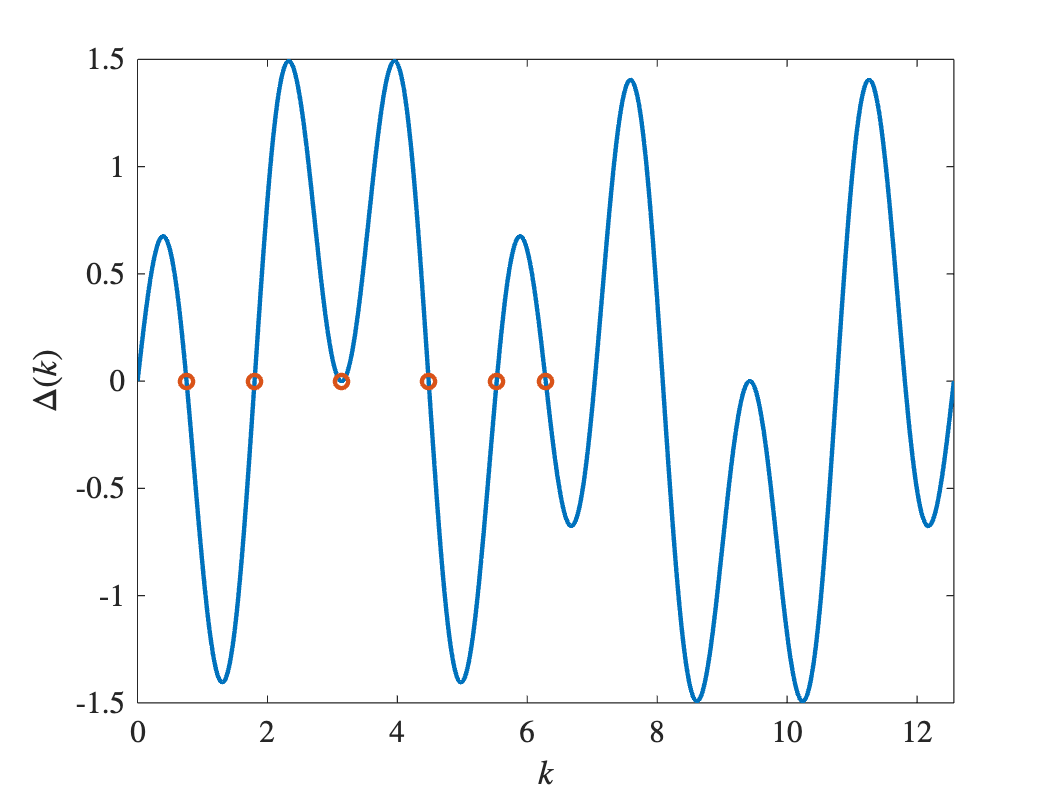

fplot(f,[0 4*pi])
k = sqrt(abs(lambda));
hold on
plot(k,zeros(size(k)),'o')
xlabel('$k$')
ylabel('$\Delta(k)$')

## Accuracy study

syms x;
kSols1=sqrt(-lambda); 
kExact = zeros(numEigs,1);
for j=1:numEigs
    kExact(j)=vpasolve(f==0,x,kSols1(j));
end
lambdaExact=-kExact.^2;
errs1=abs(lambda-lambdaExact);

Double the resolution and compute again.

nX=2*nX;
Phi = quantumGraphFromTemplate('star','LVec',LVec,'nX',nX,'robinCoeff',rC);
[~,lambda]=eigs(Phi,numEigs);
errs2=abs(lambda-lambdaExact);
errorRatio=errs1./errs2;
disp(table(lambdaExact,errs1,errs2,errorRatio))

    lambdaExact      errs1         errs2       errorRatio
    ___________    __________    __________    __________

     -0.56905      1.6865e-05    4.2164e-06           4  
      -3.2456       0.0005486    0.00013716      3.9998  
      -9.8696       0.0050723     0.0012683      3.9994  
      -9.8696       0.0050723     0.0012683      3.9994  
      -20.085        0.021002     0.0052522      3.9987  
      -30.568        0.048636      0.012165      3.9981  
      -39.478        0.081108      0.020289      3.9975  



## Accuracy study for Chebyshev discretization

nX=[30 20 20];
Phi = quantumGraphFromTemplate('star','LVec',LVec,'nX',nX,'robinCoeff',rC,'Discretization','Chebyshev');
[V,lambda]=eigs(Phi,numEigs);
errsC=abs(lambda-lambdaExact);
disp(table(lambdaExact,errsC))

    lambdaExact      errsC   
    ___________    __________

     -0.56905      2.1952e-12
      -3.2456      1.1773e-12
      -9.8696      1.5058e-11
      -9.8696      3.0198e-14
      -20.085      3.8298e-11
      -30.568      1.6687e-11
      -39.478      1.8474e-13

